clc; clearvars; close all;

% Señal Impulso

## Introducir parámetros señal Impulso

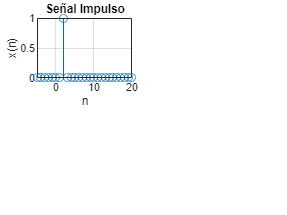

dlgtitle = 'Impulse Signal Parameters';
prompt = {'Amplitud:','Desplazamiento','n_inicio:','n_final:' };
dims = [1 35];
defect_input = {'1','2', '-5', '20'};
answer = inputdlg(prompt,dlgtitle,dims,defect_input);

A=str2num(answer{1});
n0=str2num(answer{2});
ni=str2num(answer{3});
nf=str2num(answer{4});

x1=A*[zeros(1,abs(ni)+n0)  1 zeros(1,abs(nf)-n0)]; % Señal impulso
n1=ni:nf;  % Instantes de tiempo
subplot(2,2,1);
stem(n1,x1); xlabel('n'); ylabel('x(n)'); title('Señal Impulso');grid on

## Introducir parámetros señal Escalón

dlgtitle = 'Step Signal Parameters';
prompt = {'Amplitud:','Desplazamiento','n_inicio:','n_final:' };
dims = [1 35];
defect_input = {'1','2', '-5', '20'};
answer = inputdlg(prompt,dlgtitle,dims,defect_input);

A=str2num(answer{1});

Index exceeds the number of array elements. Index must not exceed 0.

n0=str2num(answer{2});
ni=str2num(answer{3});
nf=str2num(answer{4});

x2= A*[zeros(1,abs(ni)+n0)  ones(1, abs(nf)+1-n0)  ];

n2=ni:nf;  % Instantes de tiempo
subplot(2,2,2);
stem(n2,x2); xlabel('n'); ylabel('x(n)'); title('Señal Escalón');grid on

## Señal Rampa

dlgtitle = 'Ramp Signal Parameters';
prompt = {'Pendiente:','Desplazamiento','n_inicio:','n_final:' };
dims = [1 35];
defect_input = {'1','2', '-5', '20'};
answer = inputdlg(prompt,dlgtitle,dims,defect_input);

A=str2num(answer{1}); % Pendiente de la rampa
n0=str2num(answer{2});
ni=str2num(answer{3});
nf=str2num(answer{4});


n3=ni:nf;  % Instantes de tiempo
x3=A*(n3-n0);
subplot(2,2,3);
stem(n3,x3); xlabel('n'); ylabel('x(n)'); title('Señal Rampa');grid on

## Señal Exponencial Base Real

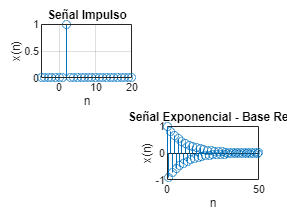

dlgtitle = 'Exponential Signal Parameters';
prompt = {'Ganancia:','Base Real:' ,'Desplazamiento:','n_inicio:','n_final:' };
dims = [1 35];
defect_input = {'1','0.9','2', '-5', '50'};
answer = inputdlg(prompt,dlgtitle,dims,defect_input);

A=str2num(answer{1}); % Ganancia de la exponencial
B=str2num(answer{2}); % Base de la exponencial (real)
n0=str2num(answer{3});
ni=str2num(answer{4});
nf=str2num(answer{5});

n4=ni:nf;  % Instantes de tiempo

x4= A*B.^(n4-n0);

subplot(2,2,4);
stem(n4,x4); xlabel('n'); ylabel('x(n)'); 
title('Señal Exponencial - Base Real');grid on

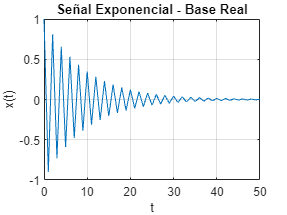


figure
plot(n4,x4); xlabel('t'); ylabel('x(t)'); 
title('Señal Exponencial - Base Real');grid on

## Señal Exponencial Base Compleja

dlgtitle = 'Exponential Signal Parameters';
prompt = {'Ganancia:','Base_R:','Base_I:' ,'Desplazamiento:','n_inicio:','n_final:' };
dims = [1 35];
defect_input = {'1','0.9','0.5','0', '-5', '50'};
answer = inputdlg(prompt,dlgtitle,dims,defect_input);

A=str2num(answer{1}); % Ganancia de la exponencial
Br=str2num(answer{2}); % Parte REAL de la base de la exponencial
Bi=str2num(answer{3}); % Parte IMAGINARIA de la exponencial

n0=str2num(answer{4});
ni=str2num(answer{5});
nf=str2num(answer{6});



B=Br+1i*Bi; %Base complej
ni=-9; %Instante de inicio
nf=5;  % Instante final
n5=ni:nf;  % Instantes de tiempo

x5= A*B.^(n5-n0);

xr= real(x5);
xi= imag(x5);
xmag= abs(x5);
xang= angle(x5);

figure
subplot(2,2,1);
stem(n5,xr); xlabel('n'); ylabel('x(n) Real'); title('Exponencial Compleja: Real');grid on

subplot(2,2,2);
stem(n5,xi); xlabel('n'); ylabel('x(n) Imaginario'); title('Exponencial Compleja: Imag');grid on

subplot(2,2,3);
stem(n5,xmag,'r'); xlabel('n'); ylabel('x(n) Mag'); title('Exponencial Compleja: Mag');grid on

subplot(2,2,4);
stem(n5,xang,'r'); xlabel('n'); ylabel('x(n) Angle'); title('Exponencial Compleja: Ang');grid on

## Señal Senoidal

dlgtitle = 'Sine Signal Parameters';
prompt = {'Ganancia:','Frecuencia Análoga:','Frecuencia Muestreo:', 'Fase (rad)' ,'Desplazamiento:','n_inicio:','n_final:' };
dims = [1 35];
defect_input = {'1.5','20','400','0.5','2', '-5', '50'};
answer = inputdlg(prompt,dlgtitle,dims,defect_input);

A=str2num(answer{1}); % Ganancia de la exponencial
Fa=str2num(answer{2}); % Frecuencia análoga
Fs=str2num(answer{3}); % Frecuencia de muestreo

Fase=str2num(answer{4}); % Fase de la señal análoga (Rad)

n0=str2num(answer{5});
ni=str2num(answer{6});
nf=str2num(answer{7});


Ts=1/Fs; %Periodo de muestreo

n6=ni:nf; %Instantes de tiempo

x6= A*sin(2*pi*Fa*(n6-n0)/Fs+ Fase);

figure
stem(n6,x6);
xlabel('n'); ylabel('x(n)'); title(['Señal Senoidal, Fa=' num2str(Fa) ' Fs= ' num2str(Fs)]);grid on